# DICOM image windowing

This live script demonstrates the use of [windowing](https://radiopaedia.org/articles/windowing-ct?lang=us) in DICOM images.

## What is windowing and why we need it?

Medical images have a large number of gray levels. It is not uncommon for them to have four thousand or more levels.

Most computer screens, on the other hand, can display only 256 levels of gray. Even if a computer screen could display more gray levels, the human eye would not be able to distinguish them.

To get around these problems, medical images are displayed using windows, i.e. instead of mapping the large grayscale in the image linearly into the 256 gray levels supported by computer screens, specific ranges of the image grayscale are emphasized.

[This article](https://towardsdatascience.com/a-matter-of-grayscale-understanding-dicom-windows-1b44344d92bd) has a good explanation of the problem and demonstrations of how windowing solves it.

The next sections in the live script demonstrates windowing with the [MATLAB DICOM functions](https://www.mathworks.com/company/newsletters/articles/accessing-data-in-dicom-files.html) and [MATLAB image processing functions](https://www.mathworks.com/help/images/).

## DICOM image selection

Select a sample image from the MATLAB image toolbox or enter your own. The list of sample images is current as of version R2020b.

To try your own images, select "(custom image)" and enter the path to the image below.

sample = "(custom image)";

If you selected "(custom image)", enter the full path to the image here, including the extension. Example: /Users/jsmith/images/dicomsample.dcm. If the file is in the same folder where the live script is, enter just the file name.

The live script folder includes a sample image from the [RSNA STR Pulmonary Embolism Detection Kaggle competition](https://www.kaggle.com/c/rsna-str-pulmonary-embolism-detection/data). This is a particularly good image to illustrate windowing because it has a large range of values, including negative values.

I recommend using this image in the live script first, to understand windowing, then try other images.

custom_image_path = "012c12fe09c3.dcm";

## Image information

Press the button below once you selected an image in the section above.

Set a full file path, based on what was chosen above.

if sample == "(custom image)"
    filePath = custom_image_path;
else
    matlabSamples = fullfile(matlabroot,'toolbox/images/imdata/');
    filePath = strcat(matlabSamples, sample);
end

if ~isfile(filePath)
    fprintf("%s does not exist", filePath)
    return
end

Read the DICOM information and the image

info = dicominfo(filePath);
image = dicomread(filePath);

Display some pieces of information about the image.

fprintf("Color type = %s", info.ColorType)

Color type = grayscale

fprintf("Width = %d, height = %d pixels", info.Width, info.Height)

Width = 512, height = 512 pixels

fprintf("Modality (acquiring equipment): %s", info.Modality)

Modality (acquiring equipment): CT

Attempt to show some fields that are not always present.

if isfield(info, "Manufacturer")
    fprintf("Equipment manufacturer and model: %s, %s", ...
        info.Manufacturer, info.ManufacturerModelName)
end
if isfield(info, "StudyDescription")
    fprintf("Study description: %s", info.StudyDescription)
end

Check if we have a grayscale image. This code is not meant for color images.

if info.ColorType ~= "grayscale"
    fprintf("Please select a grayscale image")
    return
end

Now that we know it is a grayscale image, show the pixel values range.

minGrayLevel = min(image(:));
maxGrayLevel = max(image(:));
fprintf("Minimum gray level = %d, maximum = %d", ...
    minGrayLevel, maxGrayLevel)

Minimum gray level = -2000, maximum = 3154

## Image histogram

The image histogram shows how the gray levels are distributed.

It is common for DICOM images to use dark colors (usually the lowest pixel value) as background. A histogram will show a large spike for that value, followed by significantly smaller bars for the other values.

This imbalance in the distribution may make it difficult to analyze the histogram. Change the minimum and maximum gray values shown in the histogram to analyze specific ranges of the grayscale used in the image.

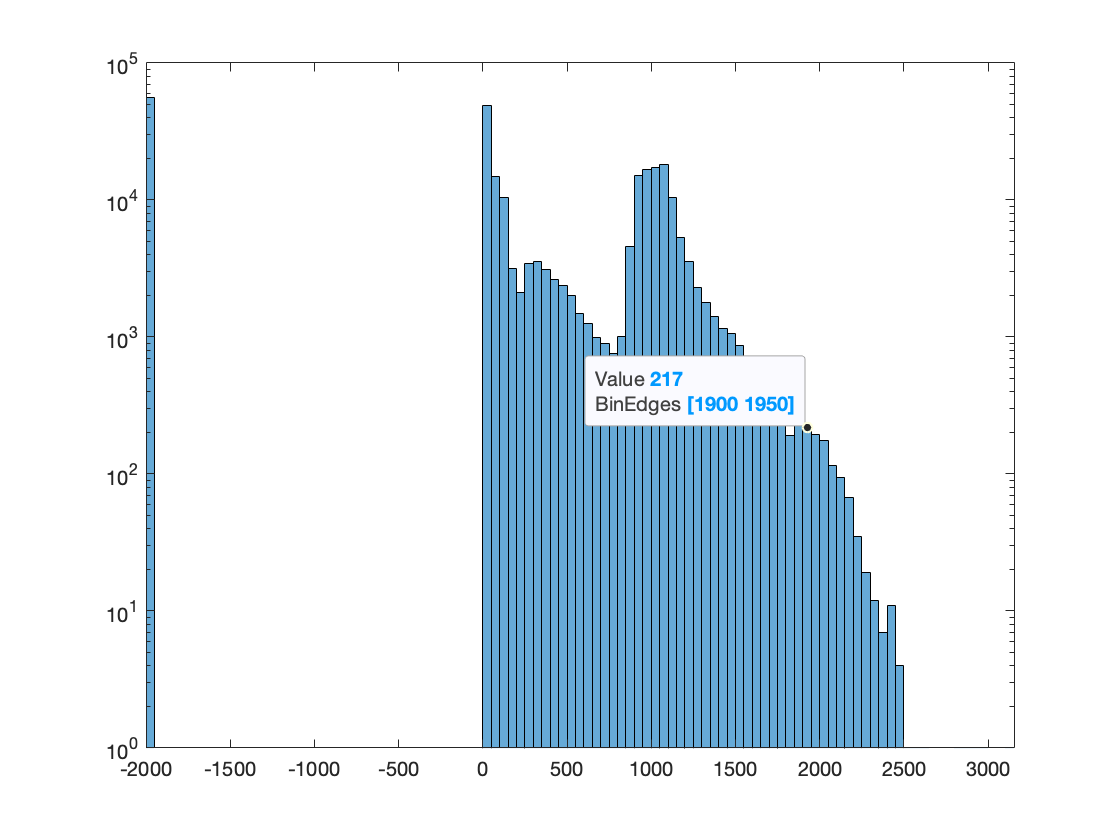

minGrayToShow = -2000;
maxGrayToShow = 3154;
 

figure
% histogram looks better than imhist imho
histogram(image)
xlim([minGrayToShow maxGrayToShow])
set(gca,'YScale','log')

## Image without adjustment

This section shows the image without performing any adjustment.

Simply showing the image results in a linear mapping of the large grayscale to the 256 scale support by monitors. The result is usually not pleasant.

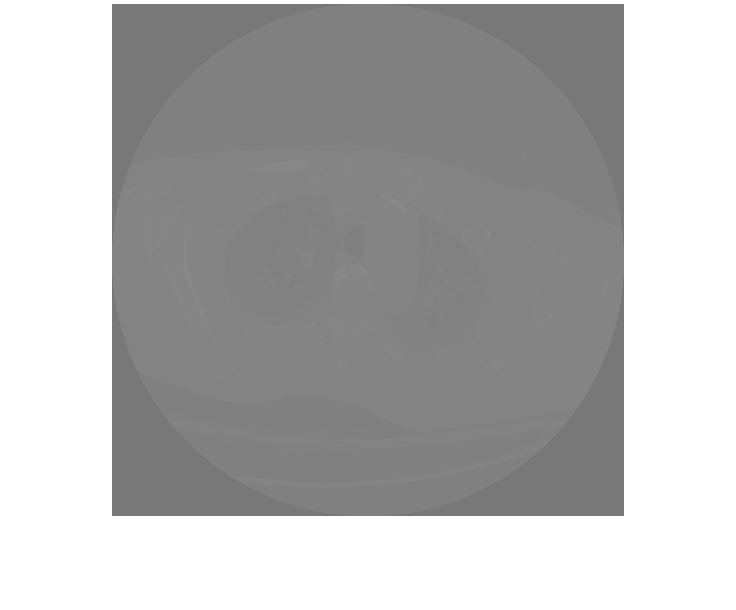

figure
imshow(image)

## Image with automatic contrast adjustment

MATLAB has [contrast-enhancing functions](https://www.mathworks.com/help/images/contrast-enhancement-techniques.html) that result in better displayed images.

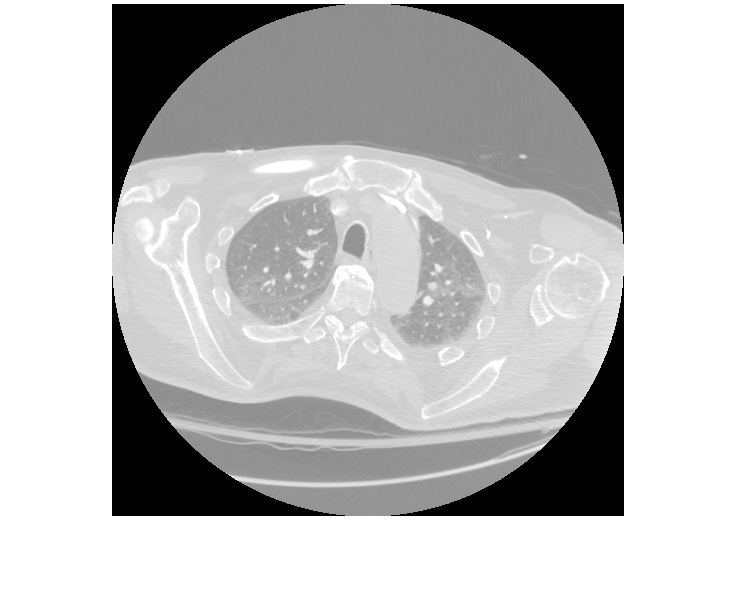

enhancement = "imadjust";
figure
imshow(feval(enhancement, image))

## Image with windowing

Although automatic contrast enhancement improves the display of the image, it does not have any information about how the image was acquired and what it represents.

This is where windowing comes into the picture (pun intended, as bad as it may be...).

### How windowing works

With windowing we specify the range we want to enhance using two parameters, the window center and the window width. These two values create a range that is mapped to the 256 levels of gray supported by computer screens.

For example, with a center set to 1,000 and a width set to 400, we would map the range [800, 1200] to the 256 levels of gray. Values below that range are mapped to zero and values above that range are mapped to 256.

### But what values to pick for center and width?

## Links to useful resources

- [A Matter of Grayscale: Understanding Dicom Windows | by Amrit Virdee](https://towardsdatascience.com/a-matter-of-grayscale-understanding-dicom-windows-1b44344d92bd): explains the concept and application of windowing in detail.

- [A Practical Introduction to CT](https://www.youtube.com/watch?v=VnpqylFYtqI): a video that explains how to work with CT images, showing how windowing is used to analyze different types of issues and other artifacts in the image.

- [How to set teh display range for this medical DICOM images](https://stackoverflow.com/q/42096890/336802) (Stackoverflow)